load("AllSolvedData100000.mat", 'AllSolvedData')
head(AllSolvedData)

          Var1              Var2    
    ________________    ____________

    1×1 occupancyMap    {6×3 double}
    1×1 occupancyMap    {5×3 double}
    1×1 occupancyMap    {7×3 double}
    1×1 occupancyMap    {4×3 double}
    1×1 occupancyMap    {3×3 double}
    1×1 occupancyMap    {6×3 double}
    1×1 occupancyMap    {6×3 double}
    1×1 occupancyMap    {4×3 double}



Database = AllSolvedData;
statespace = stateSpaceSE2;
statespace.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];


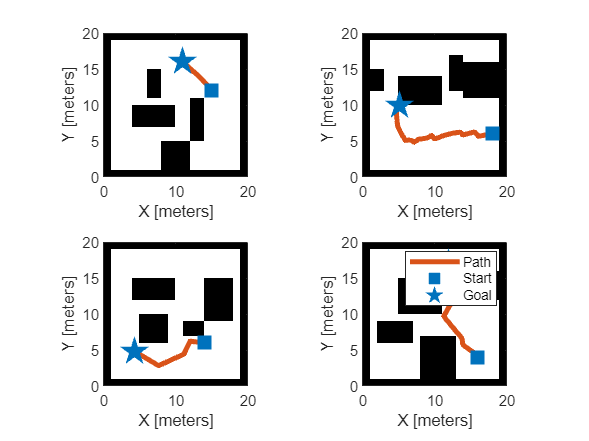

figure
for i=1:4
    subplot(2,2,i)    
    ind = randi(height(Database)); % Select a random sample
    map = Database(ind,:).Var1; % Get map from Map column of the table
    pathStates = Database(ind,:).Var2{1}; % Get path from Path column of the table
    start = pathStates(1,:); 
    goal = pathStates(end,:);
    
    % Plot the data
    show(map); 
    hold on
    plot(pathStates(:,1),pathStates(:,2),plannerLineSpec.path{:})
    plot(start(1),start(2),plannerLineSpec.start{:})
    plot(goal(1),goal(2),plannerLineSpec.goal{:})
    title("")
end
legend

mpnet = mpnetSE2;
mpnet.LossWeights = [100 100 0];
mpnet.EncodingSize = [9 9];

split = 0.8;
trainData = Database(1:800,:);
validationData = Database(801:end,:);

dsTrain = mpnetPrepareData(trainData,mpnet);
dsValidation = mpnetPrepareData(validationData,mpnet);

preparedDataSample = read(dsValidation);
preparedDataSample(1,:)

options = trainingOptions("adam",...
        MiniBatchSize=128,...
        MaxEpochs=100,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=300,...
        Plots="training-progress");

    % Train network
[net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);
    
    % Update Network property of mpnet object with net
mpnet.Network = net;



stateSamplerDL = stateSamplerMPNET(statespace,mpnet)

ind = randi(height(validationData));
map = validationData(ind,:).Var1;
start = double(validationData(ind,:).Var2{1,:}(1,:));
goal = double(validationData(ind,:).Var2{1,:}(end,:));

map(1)

stateSamplerDL.Environment = map;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateSamplerDL

numSamples =1000;
stateSamplerDL.MaxLearnedSamples = 1000;
samples = sample(stateSamplerDL, numSamples);
figure
show(map);
hold on;
plot(samples(:,1),samples(:,2),plannerLineSpec.state{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="eastoutside")



stateValidator = validatorOccupancyMap(statespace,Map=map);
stateValidator.ValidationDistance = 0.1;

start
goal

% Create RRT* planner with default uniform sampler
plannerUniformSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=1,StateSampler=stateSamplerUniform(statespace));
[pathUniformSampling,solutionInfoUniformSampling] = plan(plannerUniformSampling,start,goal);

% Visualize results for uniform sampling
figure
show(map)
hold on;
plot(pathUniformSampling.States(:,1),pathUniformSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoUniformSampling.TreeData(:,1),solutionInfoUniformSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="northeastoutside")
title("Uniform sampling")

plannerDLSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=1,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(map);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("MPNet Sampling")


% Number of runs to benchmark the planner
runCount = 30;

% Create plannerBenchmark object
pb = plannerBenchmark(stateValidator,start,goal);

% Create function handles to create planners for uniform sampling and deep
% learning-based sampling
plannerUniformSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=1);
plannerMPNetSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=1,StateSampler=stateSamplerDL);

% Create plan function
plnFcn = @(initOut,s,g)plan(initOut,s,g);

% Added both planners to plannerBenchmark object
addPlanner(pb,plnFcn,plannerUniformSamplingFcn,PlannerName="Uniform");
addPlanner(pb,plnFcn,plannerMPNetSamplingFcn,PlannerName="MPNet");

% Run planners for specified runCount
runPlanner(pb,runCount)

figure
show(pb,"executionTime")

figure
show(pb,"pathLength")

figure
show(pb,"smoothness")